clear all;
close all;
clc;

Animal = 'tph218'; %'tph199';'tph209'
Dates = {'20230826','20230827','20230828'}; % '20230602';'20230827'
totalTrial = 150;
Keys = {'roving50s','roving25s','roving10s'}; %'heavy90';'roving25s'
cellset_nums = {3,4,5}; % num of session in all sessions % start from 0
categorize = 'depth'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = [247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
%     Inscopix imaging FOV % tph199:[247; 433; 358] 
% need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = 1; %0: tph199 type orientation, 1: arc247 type orientation
% gamma = 0.9; % discount factor
% force_thres = 0.1; % remove trial which has more than force_thres at the beggining of the trial
% working_directory = 'C:\Users\NAOHIRO-YAMAUCHI\OneDrive - OIST\OIST_rotation\Doya_rotation\Makino2022\Makino2022NatureNeuroscience';
working_directory = '/home/naohiro/Desktop/Doya_rotation/analysis/Makino2022/';
% resistance_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'resistance.csv']);%,'NumHeaderLines',1);
% behavior_table = readtable(['D:\Doya_rotation\20200928_s19_heavy90' filesep 'behavior.csv']); %,'NumHeaderLines',1);
% data_folder = ['D:\Doya_rotation' filesep Date '_' Animal '_' Key];
% data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation/202308'  filesep Date '_' Animal '_' Key]; % Linux %/202308
% load ([data_folder filesep Animal '_behavior_' Date '_' Key '.mat'])
% behavior_data = behavior_neural_time_convolved_zscored;
output_dir = ['/home/naohiro/Desktop/Doya_rotation/analysis/output/231111/'];

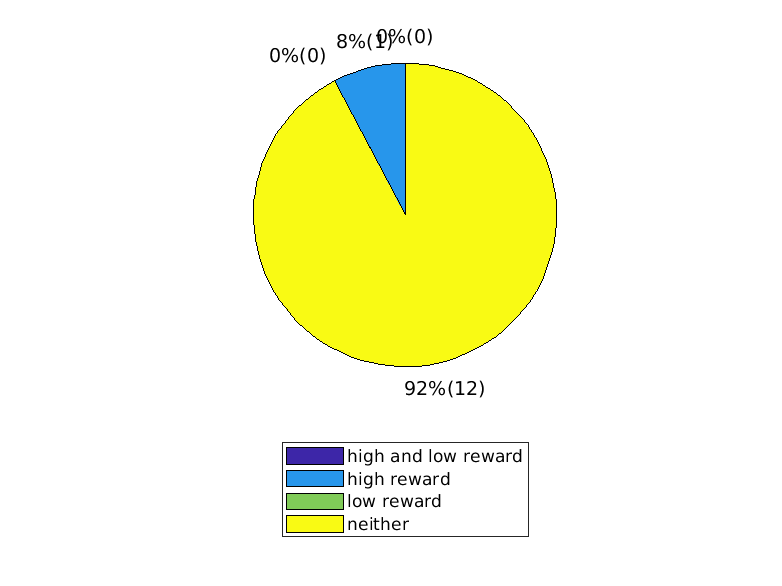

force_thr = 50;
fps = 10;
before_event = 2; %1;
after_event  = 4; %2;
data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation/202308'  filesep Dates{1} '_' Animal '_' Keys{1}]; % Linux %/202308
if contains(Keys{1},'roving')
    all_neural_property_table = readtable([data_folder filesep 'cell_traces_roving-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
    correspondences_table = readtable([data_folder filesep 'correspondences_table_roving_0.5.csv']);
else
    all_neural_property_table = readtable([data_folder filesep 'cell_traces_ordinary-props.csv']); %cell_traces_ordinary-props %all_cell_traces-props
    correspondences_table = readtable([data_folder filesep 'correspondences_table_ordinary_0.5.csv']);
end
global_acc_idx = -1 + find(strcmp(table2array(all_neural_property_table(:,'Status')),'accepted'));
all_global_acc_idx = global_acc_idx; %cell(1,length(Keys));
% determine global_acc_idx
for i_session = 1:length(Keys)
    cellset_num = cellset_nums{i_session};
    cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==cellset_num,:);
%     local_acc_idx = sort(table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'local_cell_index')), 'ascend');
    temp_global_acc_idx = table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),global_acc_idx),'global_cell_index'));
    all_global_acc_idx = intersect(all_global_acc_idx, temp_global_acc_idx);
end

% extract force aligned neural activity
% force_act       = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
eta_acts = cell(1,2);
eta_length = {0 , 0};
eta_actss = cell(1,2);
for i_session = 1:length(Keys)
    data_folder = ['/media/naohiro/ADATA HV620S/Doya_rotation/202308'  filesep Dates{i_session} '_' Animal '_' Keys{i_session}]; % Linux %/202308
    neural_activity_table = readtable([data_folder filesep 'cell_traces.csv'],'NumHeaderLines',0);%,'NumHeaderLines',1); #Linux
    neural_activity_data = table2array(neural_activity_table(:,2:size(neural_activity_table,2)));
    neural_property_table = readtable([data_folder filesep 'cell_traces-props.csv']);
    neural_property_data = table2array(neural_property_table(:,3:size(neural_property_table,2)));
    cellset_num = cellset_nums{i_session};
    cellset_correspondences_table = correspondences_table(correspondences_table.local_cellset_index==cellset_num,:);    
    local_acc_idx = table2array(cellset_correspondences_table(ismember(table2array(cellset_correspondences_table(:,'global_cell_index')),all_global_acc_idx),'local_cell_index'));
    acc_neural_activity_data = neural_activity_data(:,local_acc_idx+1);
    acc_neural_property_data = neural_property_data(local_acc_idx+1,:);

    load([data_folder filesep Animal '_behavior_' Dates{i_session} '_' Keys{i_session} '.mat']);
    force       = behavior_neural_time(:,7);
    force_idx       = find(force > force_thr);
    
    temp_force_idx = force_idx(1);
    for i = 2:length(force_idx)
        if force_idx(i) - temp_force_idx(end) >= fps
            temp_force_idx(end+1) = force_idx(i);
        end
    end
    force_idx = temp_force_idx;

% split trials and eta anlysis for detecting prediction error or action
% value
    trial        = behavior_neural_time(:,2);
    resistance   = behavior_neural_time(:,5);
    res_all  = unique(sort(resistance));
    res_high = res_all(2);
    res_low  = res_all(1);
    switch_inter = NaN;

    Keynum = regexp(Keys{i_session},'\d+','match');
    switch_inter = str2num(Keynum{1});
% action value can only calculated in session in which reward amount is
% changed
% force during trial in which reward is high (Q:action value)
% force during trial in which reward is low
    action_value_idx    = [];
    action_no_value_idx = [];
    for i = 1:length(force_idx)
        if force_idx(i)+fps < length(trial)
            temp_trial      = max(trial(force_idx(i):force_idx(i)+fps));
            temp_resistance = min(resistance(force_idx(i):force_idx(i)+fps)); % expand 1 sec to include force just before trial
        else
            temp_trial      = trial(force_idx(i));
            temp_resistance = resistance(force_idx(i));
        end
        if temp_resistance == Inf
            continue; % skip for loop
        elseif temp_trial <= totalTrial/2 && temp_resistance == res_high
            action_no_value_idx(end+1) = force_idx(i);
        elseif temp_trial <= totalTrial/2 && temp_resistance == res_low
            action_value_idx(end+1)    = force_idx(i);
        elseif temp_trial > totalTrial/2 && temp_resistance == res_high
            action_value_idx(end+1)    = force_idx(i);
        elseif temp_trial > totalTrial/2 && temp_resistance == res_low
            action_no_value_idx(end+1) = force_idx(i);
        end
    end
    eta_idxs = {action_value_idx, action_no_value_idx};
    
    for i = 1:2
        if i_session == 1;
            eta_acts{i} = zeros(size(acc_neural_activity_data,2),fps*(before_event+after_event)+1);
        end
        exception_count = 0;
        i_eta_acts = {}; %eta_actss{i};
        for j = 1:length(eta_idxs{i})
            if eta_idxs{i}(j)-fps*before_event<=0 | eta_idxs{i}(j)+fps*after_event>size(acc_neural_activity_data,1)
                exception_count = exception_count + 1;
            else
                eta_acts{i} = eta_acts{i}+transpose(acc_neural_activity_data(eta_idxs{i}(j)-fps*before_event:eta_idxs{i}(j)+fps*after_event,:));
                i_eta_acts{end+1}= transpose(acc_neural_activity_data(eta_idxs{i}(j)-fps*before_event:eta_idxs{i}(j)+fps*after_event,:));
            end
        end
    %     eta_acts{i} = eta_acts{i}/(length(eta_idxs{i})-exception_count);
        eta_length{i} = eta_length{i} + length(eta_idxs{i})-exception_count;
        i_eta_acts = reshape(cell2mat(i_eta_acts),[size(acc_neural_activity_data, 2) size(eta_acts{i},2) length(eta_idxs{i})-exception_count]); %-1]);
        eta_actss{i} = cat(3,eta_actss{i},i_eta_acts);
    end
end
% connect force aligned neural activity of different session

% test significance
max_acts = cell(1,2);
sig_cell_idxs2 = cell(1,2);
for i = 1:2
        sig_cell_idx = zeros(1,size(acc_neural_activity_data, 2));
        i_eta_acts = eta_actss{i};
        for i_cell = 1:size(acc_neural_activity_data, 2)
            [~,max_idx] = max(mean(i_eta_acts(i_cell,:,:),3)); %TODO: check the dimension of calculation
            max_acts{i} = i_eta_acts(i_cell,max_idx,:);
            [h,p] = ttest2(squeeze(i_eta_acts(i_cell,:)),squeeze(max_acts{i}),'Vartype','unequal'); %temporal,'Alpha',0.001
%             [h,p] = ttest2(squeeze(i_eta_acts(i_cell,:)),squeeze(max_acts{i}),'Vartype','unequal','Alpha',0.001); %temporal,'Alpha',0.001
            if h == 1
                sig_cell_idx(i_cell) = 1;
            else
                sig_cell_idx(i_cell) = 0;
            end
            sig_cell_idxs2{i} = sig_cell_idx;
        end
        eta_acts{i} = zscore_rows(eta_acts{i}(find(sig_cell_idx==1),:));
            [M,max_I{i}] = max(eta_acts{i},[],2);
    eta_acts{i} = cat(2,max_I{i},eta_acts{i});
    eta_acts{i} = sortrows(eta_acts{i});
    max_act_times{i} = eta_acts{i}(:,1)/10 -2;
    eta_acts{i}(:,1) = [];
end

% plot pie chart
high_low_reward_idx = sig_cell_idxs2{1} & sig_cell_idxs2{2};
high_reward_idx     = sig_cell_idxs2{1} & ~sig_cell_idxs2{2};
low_reward_idx      = ~sig_cell_idxs2{1} & sig_cell_idxs2{2};
neither_idx         = ~sig_cell_idxs2{1} & ~sig_cell_idxs2{2};
categories   = {high_low_reward_idx, high_reward_idx, low_reward_idx, neither_idx};
category_str = {'high_and_low_reward','high_reward','low_reward','neither_reward'};

data = [sum(high_low_reward_idx) sum(high_reward_idx) sum(low_reward_idx) sum(neither_idx)];
labels = {'high and low reward','high reward','low reward', 'neither'};
figure
p = pie(data); %, labels);
% title({'Percentage of neurons that reflect value among the neurons ', 'that fire when force is applied. (n=143)'});
pText = findobj(p,'Type','text');
percentValues = get(pText,'String');
txt = {['(' num2str(data(1)) ')']; ['(' num2str(data(2)) ')']; ['(' num2str(data(3)) ')']; ['(' num2str(data(4)) ')']};
combinedtxt = strcat(percentValues,txt);
pText(1).String = combinedtxt(1); pText(2).String = combinedtxt(2); 
pText(3).String = combinedtxt(3); pText(4).String = combinedtxt(4); 
legend(labels,'Location','southoutside'); 

filename = [output_dir strrep(strjoin(Dates),' ','_') '_' Animal '_' strrep(strjoin(Keys),' ','_') '_action_value_cells_pie.png'];
% filename = [output_dir Date '_'  Animal, '_' categorize '_action_value_cells_pie.png'];
saveas(gcf,filename);

function normalized_matrix = normalize_rows(matrix)
    min_values = min(matrix, [], 2);
    max_values = max(matrix, [], 2);
    range = max_values - min_values;
    normalized_matrix = (matrix - min_values) ./ range;
end

function zscored_matrix = zscore_rows(matrix)
    zscored_matrix = (matrix - mean(matrix, 2)) ./ std(matrix,0,2);
end

function pointAreas = classifyPoints(points, linePoints)
    % TODO: chack this function work correct or not.

    % points: Nx2 array of points to classify
    % linePoints: 3x2 array of points defining the line
    % pointAreas: Nx1 array indicating the area for each point (1 or 2)
%     
%     % Define the vectors representing the lines
%     lineVector1 = linePoints(2, :) - linePoints(1, :);
%     lineVector2 = linePoints(3, :) - linePoints(2, :);
    
    % Iterate through each point and classify it based on cross products
    pointAreas = zeros(size(points, 1), 1);
    for i = 1:size(points, 1)
        point = points(i, :);
        
        % Determine which side of the lines the point is on
        % classify points based on X coordinate
        if point(1) < linePoints(2,1)
            slope = (linePoints(2,2)-linePoints(1,2))/(linePoints(2,1)-linePoints(1,1));
            intercept = linePoints(1,2) - slope*linePoints(1,1);
        else
            slope = (linePoints(3,2)-linePoints(2,2))/(linePoints(3,1)-linePoints(2,1));
            intercept = linePoints(2,2) - slope*linePoints(2,1);        
        end
        lineY = slope*point(1) + intercept;
        pointAreas(i) = point(2) > lineY;
    end
end